# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Input Signals1

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
clear inputPath latestSlow latestFast
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Globals

delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
KpStatic = 50;
KiStatic = 1000;
tdStatic=0.04;

# Toggles

togRMSFreq = 0;
togSinglePoint = 0;
megaSweep = 1;  
figurePath = strcat(commonPath,'\Golden Figures');

# Model

%Model Setup
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize) %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

# Setting up gains for sweep

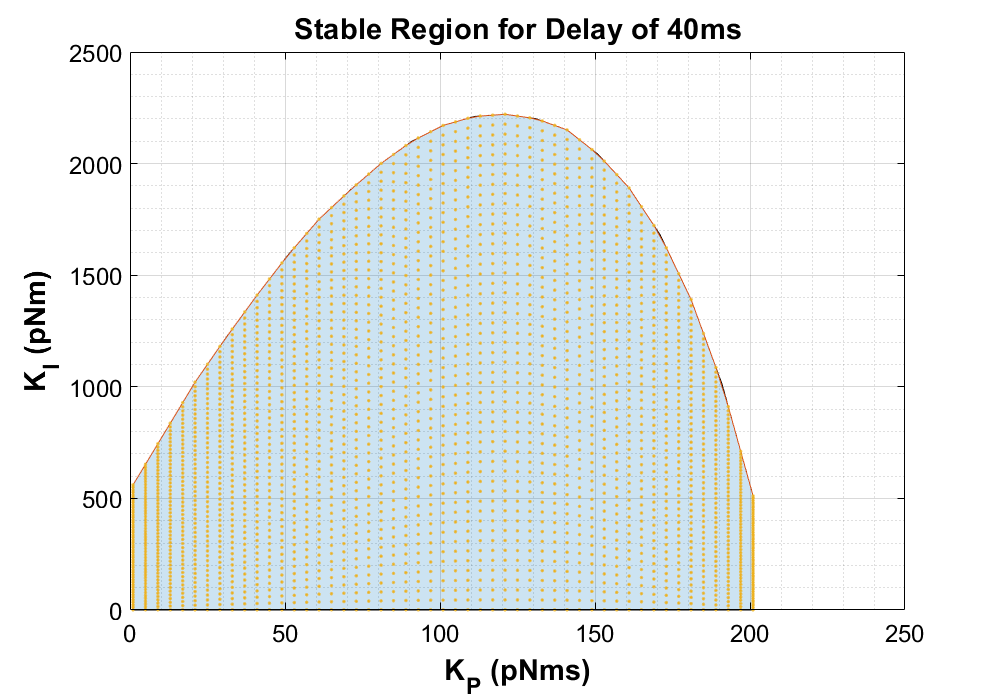

%Smooth Stability Data - Get max 04 Slice for sweeping over stable domain

slicePath = strcat(commonPath,'\Stability Sweep Data\');
latestSlice = latestTimeParse(slicePath,'04DelaySlice');
load(latestSlice)
clear slicePath latestSlice
xdata = stableSliceMax(:,1);
ydata = stableSliceMax(:,2);

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
a = area(xdata,ydata);
hold on
a.FaceAlpha = 0.2;
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('K_P (pNms)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('K_I (pNm)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title('Stable Region for Delay of 40ms','FontName','Helvetica','FontSize',22,'FontWeight','bold')
grid on
grid minor
xlim([0 250])
ylim([0 2500])

%Build Stable sampling region for Ki, Kp
Kpsize = 51;
Kisize = 51;
stableSweepKp = linspace(min(xdata),max(xdata),Kpsize);
maxKiInterp = interp1(xdata,ydata,stableSweepKp);
plot(stableSweepKp,maxKiInterp)

stableSweepKi = zeros(length(stableSweepKp),Kisize);
orderedPairs = zeros(Kpsize*Kisize,2);
opIndex = 1;
%Build Ki regions
for i = 1:length(stableSweepKp)
    stableSweepKi(i,:) = linspace(1,maxKiInterp(i),Kisize);
    orderedPairs(opIndex:opIndex - 1 + Kisize,1) = stableSweepKp(i)*ones(Kisize,1);
    orderedPairs(opIndex:opIndex - 1 + Kisize,2) = stableSweepKi(i,:)';
    opIndex = opIndex + Kisize;
end

plot(orderedPairs(:,1),orderedPairs(:,2),'.')


%Full region sweep
KpFull = linspace(1,501,Kpsize); %pNms
KiFull = linspace(1,3001,Kisize); %pNm        
KiFull = repmat(KiFull,Kpsize,1);

%Toggle for stable region or full region
stableOnly = 1;

# Ridiculous Sweep (All params minus td = 0.04)

if megaSweep == 1  
    set_param(simName,'StopTime',num2str(pureSinTime(end)),'FixedStep',num2str(pureSinTime(2) - pureSinTime(1))...
        ,'FastRestart','on')
    save_system(simName)
    
    td = 0.04;
    [nump,denp]=padeWrap(td);
    d_tf = tf(nump,denp);
    if stableOnly == 0
        Kp = KpFull;
        Ki = KiFull;
    else
        Kp = stableSweepKp;
        Ki = stableSweepKi;
    end

    switchThresh = 0:.1:5;
    decimationFactor = 5;
    pureSinDecimate = pureSin(1:decimationFactor:end, :);
    sinfreqsDecimate = sinfreqs(1:decimationFactor:end);
    
    innerSize = length(Kp)*length(Ki)*length(switchThresh);
    tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
    
    %FFT Params
    Fs = 1/(pureSinTime(2)-pureSinTime(1));
    N = 10000;   
    
    
    emptyarray = -1000*ones(1,length(pureSinTime));
    hybridStruct = repmat(struct('switchThresh',-1,'hybridOut',emptyarray,'hFit',emptyarray,'hGain',-1,'hPhase',-1,'hError',-1),...
        1,length(switchThresh));
    fullStruct = struct('Kp',-1,'Ki',-1,'inputFreq',-1,'smoothOut',emptyarray,'sGain',-1,'sPhase',-1,'sError',-1,...
        'hybridInfo',hybridStruct);
    sweepData = repmat(fullStruct,length(Kp),size(Ki,2),size(pureSinDecimate,1));
    
    emptySinglePoint = repmat(fullStruct,1,length(sinfreqsDecimate));
    
    figure
    remaining = length(Kp)*size(Ki,2);
    for i = 1:length(Kp)
        for j = 1:size(Ki,2)
            tic
            sweepData(i,j,:) = simTrackSmoothPrefill(Kp(i),Ki(i,j),d_tf,G_plant,pureSinDecimate,pureSinTime,sinfreqsDecimate,...
                emptySinglePoint,Fs,N,tLimSet,simName,switchThresh,td);
            
            toc
            remaining = remaining-1
        end
    end
    
%     tic
%     [hybridOut,hFit,hGain,hPhase,hError,smoothOut,sGain,sPhase,sError] = deconstruct(sweepData);
%     toc
    
    basepath = strcat(commonPath,'\Hybrid Performance Results');
    savePath = genFileName(basepath,'megaSweep');
    tic
    save(savePath,'sweepData','Kp','Ki','switchThresh','sinfreqsDecimate','pureSinTime','-v7.3')
    toc
end

Elapsed time is 24.856762 seconds.


remaining = 2600

Elapsed time is 24.335002 seconds.


remaining = 2599

Elapsed time is 27.453315 seconds.


remaining = 2598

Elapsed time is 24.639773 seconds.


remaining = 2597

Elapsed time is 24.140176 seconds.


remaining = 2596

Elapsed time is 24.190921 seconds.


remaining = 2595

Elapsed time is 24.105271 seconds.


remaining = 2594

Elapsed time is 24.222384 seconds.


remaining = 2593

Elapsed time is 24.298260 seconds.


remaining = 2592

Elapsed time is 24.995857 seconds.


remaining = 2591

Elapsed time is 24.348190 seconds.


remaining = 2590

Elapsed time is 24.669983 seconds.


remaining = 2589

Elapsed time is 24.417293 seconds.


remaining = 2588

Elapsed time is 24.605987 seconds.


remaining = 2587

Elapsed time is 24.120360 seconds.


remaining = 2586

Elapsed time is 24.421472 seconds.


remaining = 2585

Elapsed time is 24.592842 seconds.


remaining = 2584

Elapsed time is 24.040057 seconds.


remaining = 2583

Elapsed time is 24.113217 seconds.


remaining = 2582

Elapsed time is 24.083236 seconds.


remaining = 2581

Elapsed time is 61.358158 seconds.


remaining = 2580

Elapsed time is 24.034053 seconds.


remaining = 2579

Elapsed time is 23.987078 seconds.


remaining = 2578

Elapsed time is 23.944914 seconds.


remaining = 2577

Elapsed time is 24.008645 seconds.


remaining = 2576

Elapsed time is 23.846250 seconds.


remaining = 2575

Elapsed time is 23.818725 seconds.


remaining = 2574

Elapsed time is 23.850435 seconds.


remaining = 2573

Elapsed time is 23.811581 seconds.


remaining = 2572

Elapsed time is 23.883578 seconds.


remaining = 2571

Elapsed time is 23.944740 seconds.


remaining = 2570

Elapsed time is 23.864337 seconds.


remaining = 2569

Elapsed time is 23.929718 seconds.


remaining = 2568

Elapsed time is 23.884391 seconds.


remaining = 2567

Elapsed time is 23.984535 seconds.


remaining = 2566

Elapsed time is 23.867176 seconds.


remaining = 2565

Elapsed time is 23.966983 seconds.


remaining = 2564

Elapsed time is 23.874217 seconds.


remaining = 2563

Elapsed time is 23.840134 seconds.


remaining = 2562

Elapsed time is 23.869850 seconds.


remaining = 2561

Elapsed time is 23.849252 seconds.


remaining = 2560

Elapsed time is 24.004789 seconds.


remaining = 2559

Elapsed time is 23.851839 seconds.


remaining = 2558

Elapsed time is 23.926452 seconds.


remaining = 2557

Elapsed time is 23.860558 seconds.


remaining = 2556

Elapsed time is 23.869830 seconds.


remaining = 2555

Elapsed time is 23.841573 seconds.


remaining = 2554

Elapsed time is 23.839584 seconds.


remaining = 2553

Elapsed time is 23.830220 seconds.


remaining = 2552

Elapsed time is 23.947871 seconds.


remaining = 2551

Elapsed time is 23.859877 seconds.


remaining = 2550

Elapsed time is 23.852966 seconds.


remaining = 2549

Elapsed time is 23.843576 seconds.


remaining = 2548

Elapsed time is 23.853543 seconds.


remaining = 2547

Elapsed time is 23.861109 seconds.


remaining = 2546

Elapsed time is 23.942488 seconds.


remaining = 2545

Elapsed time is 23.846785 seconds.


remaining = 2544

Elapsed time is 23.852460 seconds.


remaining = 2543

Elapsed time is 23.873251 seconds.


remaining = 2542

Elapsed time is 23.906555 seconds.


remaining = 2541

Elapsed time is 23.975874 seconds.


remaining = 2540

Elapsed time is 23.875099 seconds.


remaining = 2539

Elapsed time is 23.889177 seconds.


remaining = 2538

Elapsed time is 23.942959 seconds.


remaining = 2537

Elapsed time is 23.950746 seconds.


remaining = 2536

Elapsed time is 23.916360 seconds.


remaining = 2535

Elapsed time is 24.016335 seconds.


remaining = 2534

Elapsed time is 23.951384 seconds.


remaining = 2533

Elapsed time is 23.983160 seconds.


remaining = 2532

Elapsed time is 23.974387 seconds.


remaining = 2531

Elapsed time is 24.018005 seconds.


remaining = 2530

Elapsed time is 24.066484 seconds.


remaining = 2529

Elapsed time is 24.127742 seconds.


remaining = 2528

Elapsed time is 24.053931 seconds.


remaining = 2527

Elapsed time is 24.070633 seconds.


remaining = 2526

Elapsed time is 24.056470 seconds.


remaining = 2525

Elapsed time is 24.071405 seconds.


remaining = 2524

Elapsed time is 24.121566 seconds.


remaining = 2523

Elapsed time is 24.077026 seconds.


remaining = 2522

Elapsed time is 24.102618 seconds.


remaining = 2521

Elapsed time is 24.150383 seconds.


remaining = 2520

Elapsed time is 24.289145 seconds.


remaining = 2519

Elapsed time is 24.264184 seconds.


remaining = 2518

Elapsed time is 24.166120 seconds.


remaining = 2517

Elapsed time is 24.162905 seconds.


remaining = 2516

Elapsed time is 24.177888 seconds.


remaining = 2515

Elapsed time is 24.148096 seconds.


remaining = 2514

Elapsed time is 24.233726 seconds.


remaining = 2513

Elapsed time is 24.141605 seconds.


remaining = 2512

Elapsed time is 24.123665 seconds.


remaining = 2511

Elapsed time is 24.150585 seconds.


remaining = 2510

Elapsed time is 24.135409 seconds.


remaining = 2509

Elapsed time is 24.244444 seconds.


remaining = 2508

Elapsed time is 24.153635 seconds.


remaining = 2507

Elapsed time is 24.156506 seconds.


remaining = 2506

Elapsed time is 24.166012 seconds.


remaining = 2505

Elapsed time is 24.160232 seconds.


remaining = 2504

Elapsed time is 24.256554 seconds.


remaining = 2503

Elapsed time is 24.150540 seconds.


remaining = 2502

Elapsed time is 24.151647 seconds.


remaining = 2501

Elapsed time is 24.090570 seconds.


remaining = 2500

Elapsed time is 24.234050 seconds.


remaining = 2499

Elapsed time is 24.163525 seconds.


remaining = 2498

Elapsed time is 24.185254 seconds.


remaining = 2497

Elapsed time is 24.172259 seconds.


remaining = 2496

Elapsed time is 24.174660 seconds.


remaining = 2495

Elapsed time is 24.217523 seconds.


remaining = 2494

Elapsed time is 24.186194 seconds.


remaining = 2493

Elapsed time is 24.163080 seconds.


remaining = 2492

Elapsed time is 24.283152 seconds.


remaining = 2491

Elapsed time is 24.167191 seconds.


remaining = 2490

Elapsed time is 24.243462 seconds.


remaining = 2489

Elapsed time is 24.176098 seconds.


remaining = 2488

Elapsed time is 24.160778 seconds.


remaining = 2487

Elapsed time is 24.185882 seconds.


remaining = 2486

Elapsed time is 24.220869 seconds.


remaining = 2485

Elapsed time is 24.348514 seconds.


remaining = 2484

Elapsed time is 24.184891 seconds.


remaining = 2483

Elapsed time is 24.194768 seconds.


remaining = 2482

Elapsed time is 24.248886 seconds.


remaining = 2481

Elapsed time is 24.170144 seconds.


remaining = 2480

Elapsed time is 24.207106 seconds.


remaining = 2479

Elapsed time is 24.203510 seconds.


remaining = 2478

Elapsed time is 24.197188 seconds.


remaining = 2477

Elapsed time is 24.271064 seconds.


remaining = 2476

Elapsed time is 24.166504 seconds.


remaining = 2475

Elapsed time is 24.173151 seconds.


remaining = 2474

Elapsed time is 24.146507 seconds.


remaining = 2473

Elapsed time is 24.224552 seconds.


remaining = 2472

Elapsed time is 24.152047 seconds.


remaining = 2471

Elapsed time is 24.209831 seconds.


remaining = 2470

Elapsed time is 24.136102 seconds.


remaining = 2469

Elapsed time is 24.257113 seconds.


remaining = 2468

Elapsed time is 24.190263 seconds.


remaining = 2467

Elapsed time is 24.176301 seconds.


remaining = 2466

Elapsed time is 24.208096 seconds.


remaining = 2465

Elapsed time is 24.255865 seconds.


remaining = 2464

Elapsed time is 24.162985 seconds.


remaining = 2463

Elapsed time is 24.189189 seconds.


remaining = 2462

Elapsed time is 24.189021 seconds.


remaining = 2461

Elapsed time is 24.265677 seconds.


remaining = 2460

Elapsed time is 24.141640 seconds.


remaining = 2459

Elapsed time is 24.172260 seconds.


remaining = 2458

Elapsed time is 24.117340 seconds.


remaining = 2457

Elapsed time is 24.230904 seconds.


remaining = 2456

Elapsed time is 24.135435 seconds.


remaining = 2455

Elapsed time is 24.279943 seconds.


remaining = 2454

Elapsed time is 24.203078 seconds.


remaining = 2453

Elapsed time is 24.247709 seconds.


remaining = 2452

Elapsed time is 24.212488 seconds.


remaining = 2451

Elapsed time is 24.166573 seconds.


remaining = 2450

Elapsed time is 24.165777 seconds.


remaining = 2449

Elapsed time is 24.264266 seconds.


remaining = 2448

Elapsed time is 24.190651 seconds.


remaining = 2447

Elapsed time is 24.205796 seconds.


remaining = 2446

Elapsed time is 24.290144 seconds.


remaining = 2445

Elapsed time is 24.177118 seconds.


remaining = 2444

Elapsed time is 24.210595 seconds.


remaining = 2443

Elapsed time is 24.180963 seconds.


remaining = 2442

Elapsed time is 24.300440 seconds.


remaining = 2441

Elapsed time is 24.177355 seconds.


remaining = 2440

Elapsed time is 24.197529 seconds.


remaining = 2439

Elapsed time is 24.183238 seconds.


remaining = 2438

Elapsed time is 24.201534 seconds.


remaining = 2437

Elapsed time is 24.192630 seconds.


remaining = 2436

Elapsed time is 24.214683 seconds.


remaining = 2435

Elapsed time is 24.294828 seconds.


remaining = 2434

Elapsed time is 24.161416 seconds.


remaining = 2433

Elapsed time is 24.185809 seconds.


remaining = 2432

Elapsed time is 24.173337 seconds.


remaining = 2431

Elapsed time is 24.228909 seconds.


remaining = 2430

Elapsed time is 24.219776 seconds.


remaining = 2429

Elapsed time is 24.182960 seconds.


remaining = 2428

Elapsed time is 24.244166 seconds.


remaining = 2427

Elapsed time is 24.155501 seconds.


remaining = 2426

Elapsed time is 24.168591 seconds.


remaining = 2425

Elapsed time is 24.259098 seconds.


remaining = 2424

Elapsed time is 24.174394 seconds.


remaining = 2423

Elapsed time is 24.228923 seconds.


remaining = 2422

Elapsed time is 24.208603 seconds.


remaining = 2421

Elapsed time is 24.276257 seconds.


remaining = 2420

Elapsed time is 24.155920 seconds.


remaining = 2419

Elapsed time is 24.192632 seconds.


remaining = 2418

Elapsed time is 24.369268 seconds.


remaining = 2417

Elapsed time is 24.186040 seconds.


remaining = 2416

Elapsed time is 24.199374 seconds.


remaining = 2415

Elapsed time is 24.286430 seconds.


remaining = 2414

Elapsed time is 24.230959 seconds.


remaining = 2413

Elapsed time is 24.189798 seconds.


remaining = 2412

Elapsed time is 24.250788 seconds.


remaining = 2411

Elapsed time is 24.286732 seconds.


remaining = 2410

Elapsed time is 24.192618 seconds.


remaining = 2409

Elapsed time is 24.278425 seconds.


remaining = 2408

Elapsed time is 24.278250 seconds.


remaining = 2407

Elapsed time is 24.194799 seconds.


remaining = 2406

Elapsed time is 24.252107 seconds.


remaining = 2405

Elapsed time is 24.268626 seconds.


remaining = 2404

Elapsed time is 24.155158 seconds.


remaining = 2403

Elapsed time is 24.203478 seconds.


remaining = 2402

Elapsed time is 24.299513 seconds.


remaining = 2401

Elapsed time is 24.159541 seconds.


remaining = 2400

Elapsed time is 24.180243 seconds.


remaining = 2399

Elapsed time is 24.244045 seconds.


remaining = 2398

Elapsed time is 24.199288 seconds.


remaining = 2397

Elapsed time is 24.203958 seconds.


remaining = 2396

Elapsed time is 24.251596 seconds.


remaining = 2395

Elapsed time is 24.177031 seconds.


remaining = 2394

Elapsed time is 24.239422 seconds.


remaining = 2393

Elapsed time is 24.304883 seconds.


remaining = 2392

Elapsed time is 24.184822 seconds.


remaining = 2391

Elapsed time is 24.277566 seconds.


remaining = 2390

Elapsed time is 24.205146 seconds.


remaining = 2389

Elapsed time is 24.195265 seconds.


remaining = 2388

Elapsed time is 24.271870 seconds.


remaining = 2387

Elapsed time is 24.175284 seconds.


remaining = 2386

Elapsed time is 24.184933 seconds.


remaining = 2385

Elapsed time is 24.335276 seconds.


remaining = 2384

Elapsed time is 24.213405 seconds.


remaining = 2383

Elapsed time is 24.205646 seconds.


remaining = 2382

Elapsed time is 24.299654 seconds.


remaining = 2381

Elapsed time is 24.227957 seconds.


remaining = 2380

Elapsed time is 24.327591 seconds.


remaining = 2379

Elapsed time is 24.272148 seconds.


remaining = 2378

Elapsed time is 24.226559 seconds.


remaining = 2377

Elapsed time is 24.302705 seconds.


remaining = 2376

Elapsed time is 24.230561 seconds.


remaining = 2375

Elapsed time is 24.262593 seconds.


remaining = 2374

Elapsed time is 24.326230 seconds.


remaining = 2373

Elapsed time is 24.237474 seconds.


remaining = 2372

Elapsed time is 24.221738 seconds.


remaining = 2371

Elapsed time is 24.516557 seconds.


remaining = 2370

Elapsed time is 24.257317 seconds.


remaining = 2369

Elapsed time is 24.335924 seconds.


remaining = 2368

Elapsed time is 24.274712 seconds.


remaining = 2367

Elapsed time is 24.328854 seconds.


remaining = 2366

Elapsed time is 24.368350 seconds.


remaining = 2365

Elapsed time is 24.277362 seconds.


remaining = 2364

Elapsed time is 24.346155 seconds.


remaining = 2363

Elapsed time is 24.780454 seconds.


remaining = 2362

Elapsed time is 24.360239 seconds.


remaining = 2361

Elapsed time is 24.412040 seconds.


remaining = 2360

Elapsed time is 24.316401 seconds.


remaining = 2359

Elapsed time is 24.288148 seconds.


remaining = 2358

Elapsed time is 24.426715 seconds.


remaining = 2357

Elapsed time is 24.347292 seconds.


remaining = 2356

Elapsed time is 24.426715 seconds.


remaining = 2355

Elapsed time is 24.332307 seconds.


remaining = 2354

Elapsed time is 24.364708 seconds.


remaining = 2353

Elapsed time is 24.410034 seconds.


remaining = 2352

Elapsed time is 24.380344 seconds.


remaining = 2351

Elapsed time is 24.500077 seconds.


remaining = 2350

Elapsed time is 24.428163 seconds.


remaining = 2349

Elapsed time is 24.425546 seconds.


remaining = 2348

Elapsed time is 24.430960 seconds.


remaining = 2347

Elapsed time is 24.389797 seconds.


remaining = 2346

Elapsed time is 24.455922 seconds.


remaining = 2345

Elapsed time is 24.425944 seconds.


remaining = 2344

Elapsed time is 24.487413 seconds.


remaining = 2343

Elapsed time is 24.526708 seconds.


remaining = 2342

Elapsed time is 24.415421 seconds.


remaining = 2341

Elapsed time is 24.477113 seconds.


remaining = 2340

Elapsed time is 24.414169 seconds.


remaining = 2339

Elapsed time is 24.487659 seconds.


remaining = 2338

Elapsed time is 24.455890 seconds.


remaining = 2337

Elapsed time is 24.493209 seconds.


remaining = 2336

Elapsed time is 24.421206 seconds.


remaining = 2335

Elapsed time is 24.453450 seconds.


remaining = 2334

Elapsed time is 24.596355 seconds.


remaining = 2333

Elapsed time is 24.464157 seconds.


remaining = 2332

Elapsed time is 24.591908 seconds.


remaining = 2331

Elapsed time is 24.469253 seconds.


remaining = 2330

Elapsed time is 24.529607 seconds.


remaining = 2329

Elapsed time is 24.458741 seconds.


remaining = 2328

Elapsed time is 24.573410 seconds.


remaining = 2327

Elapsed time is 24.493736 seconds.


remaining = 2326

Elapsed time is 24.517349 seconds.


remaining = 2325

Elapsed time is 24.540735 seconds.


remaining = 2324

Elapsed time is 25.217584 seconds.


remaining = 2323

Elapsed time is 25.724118 seconds.


remaining = 2322

Elapsed time is 25.316872 seconds.


remaining = 2321

Elapsed time is 24.868200 seconds.


remaining = 2320

Elapsed time is 24.525968 seconds.


remaining = 2319

Elapsed time is 24.565244 seconds.


remaining = 2318

Elapsed time is 24.488937 seconds.


remaining = 2317

Elapsed time is 24.549018 seconds.


remaining = 2316

Elapsed time is 24.504366 seconds.


remaining = 2315

Elapsed time is 24.524396 seconds.


remaining = 2314

Elapsed time is 24.497487 seconds.


remaining = 2313

Elapsed time is 24.569395 seconds.


remaining = 2312

Elapsed time is 24.503373 seconds.


remaining = 2311

Elapsed time is 24.554995 seconds.


remaining = 2310

Elapsed time is 24.503113 seconds.


remaining = 2309

Elapsed time is 24.605552 seconds.


remaining = 2308

Elapsed time is 24.506568 seconds.


remaining = 2307

Elapsed time is 24.699704 seconds.


remaining = 2306

Elapsed time is 24.504979 seconds.


remaining = 2305

Elapsed time is 24.573144 seconds.


remaining = 2304

Elapsed time is 24.513149 seconds.


remaining = 2303

Elapsed time is 24.581986 seconds.


remaining = 2302

Elapsed time is 24.508933 seconds.


remaining = 2301

Elapsed time is 24.611067 seconds.


remaining = 2300

Elapsed time is 24.546303 seconds.


remaining = 2299

Elapsed time is 24.618337 seconds.


remaining = 2298

Elapsed time is 24.503247 seconds.


remaining = 2297

Elapsed time is 24.597421 seconds.


remaining = 2296

Elapsed time is 24.569283 seconds.


remaining = 2295

Elapsed time is 24.502620 seconds.


remaining = 2294

Elapsed time is 24.597553 seconds.


remaining = 2293

Elapsed time is 24.507835 seconds.


remaining = 2292

Elapsed time is 24.605770 seconds.


remaining = 2291

Elapsed time is 24.489726 seconds.


remaining = 2290

Elapsed time is 24.570767 seconds.


remaining = 2289

Elapsed time is 24.517852 seconds.


remaining = 2288

Elapsed time is 24.621056 seconds.


remaining = 2287

Elapsed time is 24.503885 seconds.


remaining = 2286

Elapsed time is 24.544894 seconds.


remaining = 2285

Elapsed time is 24.489344 seconds.


remaining = 2284

Elapsed time is 24.608173 seconds.


remaining = 2283

Elapsed time is 24.526118 seconds.


remaining = 2282

Elapsed time is 24.604405 seconds.


remaining = 2281

Elapsed time is 24.519890 seconds.


remaining = 2280

Elapsed time is 24.568245 seconds.


remaining = 2279

Elapsed time is 24.523602 seconds.


remaining = 2278

Elapsed time is 24.597933 seconds.


remaining = 2277

Elapsed time is 24.538825 seconds.


remaining = 2276

Elapsed time is 24.493362 seconds.


remaining = 2275

Elapsed time is 24.594762 seconds.


remaining = 2274

Elapsed time is 24.477168 seconds.


remaining = 2273

Elapsed time is 24.578166 seconds.


remaining = 2272

Elapsed time is 24.522365 seconds.


remaining = 2271

Elapsed time is 24.613571 seconds.


remaining = 2270

Elapsed time is 24.682336 seconds.


remaining = 2269

Elapsed time is 24.588241 seconds.


remaining = 2268

Elapsed time is 24.539837 seconds.


remaining = 2267

Elapsed time is 24.605121 seconds.


remaining = 2266

Elapsed time is 24.554373 seconds.


remaining = 2265

Elapsed time is 24.731019 seconds.


remaining = 2264

Elapsed time is 24.542438 seconds.


remaining = 2263

Elapsed time is 24.568457 seconds.


remaining = 2262

Elapsed time is 24.516495 seconds.


remaining = 2261

Elapsed time is 24.596688 seconds.


remaining = 2260

Elapsed time is 24.619830 seconds.


remaining = 2259

Elapsed time is 24.488706 seconds.


remaining = 2258

Elapsed time is 24.571516 seconds.


remaining = 2257

Elapsed time is 24.500098 seconds.


remaining = 2256

Elapsed time is 24.643794 seconds.


remaining = 2255

Elapsed time is 24.538250 seconds.


remaining = 2254

Elapsed time is 24.605010 seconds.


remaining = 2253

Elapsed time is 24.552132 seconds.


remaining = 2252

Elapsed time is 24.612038 seconds.


remaining = 2251

Elapsed time is 24.515578 seconds.


remaining = 2250

Elapsed time is 24.595985 seconds.


remaining = 2249

Elapsed time is 24.516460 seconds.


remaining = 2248

Elapsed time is 24.612063 seconds.


remaining = 2247

Elapsed time is 24.547323 seconds.


remaining = 2246

Elapsed time is 24.620401 seconds.


remaining = 2245

Elapsed time is 24.565967 seconds.


remaining = 2244

Elapsed time is 24.602547 seconds.


remaining = 2243

Elapsed time is 24.500888 seconds.


remaining = 2242

Elapsed time is 24.587212 seconds.


remaining = 2241

Elapsed time is 24.580811 seconds.


remaining = 2240

Elapsed time is 24.509977 seconds.


remaining = 2239

Elapsed time is 24.635233 seconds.


remaining = 2238

Elapsed time is 24.485119 seconds.


remaining = 2237

Elapsed time is 24.586951 seconds.


remaining = 2236

Elapsed time is 24.487412 seconds.


remaining = 2235

Elapsed time is 24.609581 seconds.


remaining = 2234

Elapsed time is 24.475397 seconds.


remaining = 2233

Elapsed time is 24.730755 seconds.


remaining = 2232

Elapsed time is 24.509588 seconds.


remaining = 2231

Elapsed time is 24.605940 seconds.


remaining = 2230

Elapsed time is 24.503567 seconds.


remaining = 2229

Elapsed time is 24.598305 seconds.


remaining = 2228

Elapsed time is 24.506938 seconds.


remaining = 2227

Elapsed time is 24.561996 seconds.


remaining = 2226

Elapsed time is 24.565780 seconds.


remaining = 2225

Elapsed time is 24.595447 seconds.


remaining = 2224

Elapsed time is 24.830809 seconds.


remaining = 2223

Elapsed time is 24.520481 seconds.


remaining = 2222

Elapsed time is 24.605674 seconds.


remaining = 2221

Elapsed time is 24.484170 seconds.


remaining = 2220

Elapsed time is 24.589582 seconds.


remaining = 2219

Elapsed time is 24.511174 seconds.


remaining = 2218

Elapsed time is 24.590807 seconds.


remaining = 2217

Elapsed time is 24.458718 seconds.


remaining = 2216

Elapsed time is 24.606429 seconds.


remaining = 2215

Elapsed time is 24.491480 seconds.


remaining = 2214

Elapsed time is 24.587464 seconds.


remaining = 2213

Elapsed time is 24.549591 seconds.


remaining = 2212

Elapsed time is 24.644670 seconds.


remaining = 2211

Elapsed time is 24.520964 seconds.


remaining = 2210

Elapsed time is 24.655355 seconds.


remaining = 2209

Elapsed time is 24.476843 seconds.


remaining = 2208

Elapsed time is 24.595593 seconds.


remaining = 2207

Elapsed time is 24.494216 seconds.


remaining = 2206

Elapsed time is 24.646403 seconds.


remaining = 2205

Elapsed time is 24.589017 seconds.


remaining = 2204

Elapsed time is 24.517270 seconds.


remaining = 2203

Elapsed time is 24.599350 seconds.


remaining = 2202

Elapsed time is 24.505271 seconds.


remaining = 2201

Elapsed time is 24.661740 seconds.


remaining = 2200

Elapsed time is 24.531323 seconds.


remaining = 2199

Elapsed time is 24.603856 seconds.


remaining = 2198

Elapsed time is 24.517666 seconds.


remaining = 2197

Elapsed time is 24.762336 seconds.


remaining = 2196

Elapsed time is 24.569119 seconds.


remaining = 2195

Elapsed time is 24.610746 seconds.


remaining = 2194

Elapsed time is 24.531578 seconds.


remaining = 2193

Elapsed time is 24.597070 seconds.


remaining = 2192

Elapsed time is 24.510816 seconds.


remaining = 2191

Elapsed time is 24.589790 seconds.


remaining = 2190

Elapsed time is 24.499823 seconds.


remaining = 2189

Elapsed time is 24.571434 seconds.


remaining = 2188

Elapsed time is 24.702245 seconds.


remaining = 2187

Elapsed time is 24.491056 seconds.


remaining = 2186

Elapsed time is 24.605601 seconds.


remaining = 2185

Elapsed time is 24.515304 seconds.


remaining = 2184

Elapsed time is 24.620577 seconds.


remaining = 2183

Elapsed time is 24.508027 seconds.


remaining = 2182

Elapsed time is 24.587292 seconds.


remaining = 2181

Elapsed time is 24.487539 seconds.


remaining = 2180

Elapsed time is 24.584026 seconds.


remaining = 2179

Elapsed time is 24.526373 seconds.


remaining = 2178

Elapsed time is 24.602085 seconds.


remaining = 2177

Elapsed time is 24.523713 seconds.


remaining = 2176

Elapsed time is 24.602528 seconds.


remaining = 2175

Elapsed time is 24.533210 seconds.


remaining = 2174

Elapsed time is 24.634714 seconds.


remaining = 2173

Elapsed time is 24.554386 seconds.


remaining = 2172

Elapsed time is 24.593337 seconds.


remaining = 2171

Elapsed time is 24.522421 seconds.


remaining = 2170

Elapsed time is 24.597422 seconds.


remaining = 2169

Elapsed time is 24.640419 seconds.


remaining = 2168

Elapsed time is 24.487733 seconds.


remaining = 2167

Elapsed time is 24.591180 seconds.


remaining = 2166

Elapsed time is 24.535243 seconds.


remaining = 2165

Elapsed time is 24.613466 seconds.


remaining = 2164

Elapsed time is 24.531816 seconds.


remaining = 2163

Elapsed time is 24.580293 seconds.


remaining = 2162

Elapsed time is 24.550506 seconds.


remaining = 2161

Elapsed time is 24.594939 seconds.


remaining = 2160

Elapsed time is 24.647231 seconds.


remaining = 2159

Elapsed time is 24.612260 seconds.


remaining = 2158

Elapsed time is 24.495484 seconds.


remaining = 2157

Elapsed time is 24.647246 seconds.


remaining = 2156

Elapsed time is 24.485609 seconds.


remaining = 2155

Elapsed time is 24.605175 seconds.


remaining = 2154

Elapsed time is 24.502656 seconds.


remaining = 2153

Elapsed time is 24.636945 seconds.


remaining = 2152

Elapsed time is 24.611989 seconds.


remaining = 2151

Elapsed time is 24.519611 seconds.


remaining = 2150

Elapsed time is 24.589133 seconds.


remaining = 2149

Elapsed time is 24.545829 seconds.


remaining = 2148

Elapsed time is 24.685106 seconds.


remaining = 2147

Elapsed time is 24.660545 seconds.


remaining = 2146

Elapsed time is 24.595116 seconds.


remaining = 2145

Elapsed time is 24.516264 seconds.


remaining = 2144

Elapsed time is 24.625640 seconds.


remaining = 2143

Elapsed time is 24.525367 seconds.


remaining = 2142

Elapsed time is 24.591806 seconds.


remaining = 2141

Elapsed time is 24.522251 seconds.


remaining = 2140

Elapsed time is 24.605493 seconds.


remaining = 2139

Elapsed time is 24.499006 seconds.


remaining = 2138

Elapsed time is 24.635361 seconds.


remaining = 2137

Elapsed time is 24.519195 seconds.


remaining = 2136

Elapsed time is 24.613855 seconds.


remaining = 2135

Elapsed time is 24.610097 seconds.


remaining = 2134

Elapsed time is 24.496358 seconds.


remaining = 2133

Elapsed time is 24.645865 seconds.


remaining = 2132

Elapsed time is 24.533527 seconds.


remaining = 2131

Elapsed time is 24.592721 seconds.


remaining = 2130

Elapsed time is 24.533783 seconds.


remaining = 2129

Elapsed time is 24.572840 seconds.


remaining = 2128

Elapsed time is 24.533072 seconds.


remaining = 2127

Elapsed time is 24.573925 seconds.


remaining = 2126

Elapsed time is 24.495515 seconds.


remaining = 2125

Elapsed time is 24.587425 seconds.


remaining = 2124

Elapsed time is 24.499940 seconds.


remaining = 2123

Elapsed time is 24.768988 seconds.


remaining = 2122

Elapsed time is 24.512682 seconds.


remaining = 2121

Elapsed time is 24.599682 seconds.


remaining = 2120

Elapsed time is 24.519831 seconds.


remaining = 2119

Elapsed time is 24.619150 seconds.


remaining = 2118

Elapsed time is 24.743838 seconds.


remaining = 2117

Elapsed time is 24.528095 seconds.


remaining = 2116

Elapsed time is 24.594683 seconds.


remaining = 2115

Elapsed time is 24.511638 seconds.


remaining = 2114

Elapsed time is 24.587745 seconds.


remaining = 2113

Elapsed time is 24.524667 seconds.


remaining = 2112

Elapsed time is 24.595858 seconds.


remaining = 2111

Elapsed time is 24.521841 seconds.


remaining = 2110

Elapsed time is 24.546465 seconds.


remaining = 2109

Elapsed time is 24.544298 seconds.


remaining = 2108

Elapsed time is 24.646264 seconds.


remaining = 2107

Elapsed time is 24.541951 seconds.


remaining = 2106

Elapsed time is 24.593455 seconds.


remaining = 2105

Elapsed time is 24.522385 seconds.


remaining = 2104

Elapsed time is 24.688720 seconds.


remaining = 2103

Elapsed time is 24.564644 seconds.


remaining = 2102

Elapsed time is 24.619943 seconds.


remaining = 2101

Elapsed time is 24.571897 seconds.


remaining = 2100

Elapsed time is 24.662242 seconds.


remaining = 2099

Elapsed time is 24.621960 seconds.


remaining = 2098

Elapsed time is 24.561084 seconds.


remaining = 2097

Elapsed time is 24.643813 seconds.


remaining = 2096

Elapsed time is 24.510829 seconds.


remaining = 2095

Elapsed time is 24.664867 seconds.


remaining = 2094

Elapsed time is 24.573833 seconds.


remaining = 2093

Elapsed time is 24.605999 seconds.


remaining = 2092

Elapsed time is 24.589153 seconds.


remaining = 2091

Elapsed time is 24.625318 seconds.


remaining = 2090

Elapsed time is 24.547678 seconds.


remaining = 2089

Elapsed time is 24.667689 seconds.


remaining = 2088

Elapsed time is 24.608964 seconds.


remaining = 2087

Elapsed time is 24.653275 seconds.


remaining = 2086

Elapsed time is 24.747998 seconds.


remaining = 2085

Elapsed time is 24.646050 seconds.


remaining = 2084

Elapsed time is 24.568290 seconds.


remaining = 2083

Elapsed time is 24.673866 seconds.


remaining = 2082

Elapsed time is 24.680473 seconds.


remaining = 2081

Elapsed time is 24.567271 seconds.


remaining = 2080

Elapsed time is 24.701475 seconds.


remaining = 2079

Elapsed time is 24.599438 seconds.


remaining = 2078

Elapsed time is 24.927135 seconds.


remaining = 2077

Elapsed time is 24.617687 seconds.


remaining = 2076

Elapsed time is 24.713698 seconds.


remaining = 2075

Elapsed time is 24.623604 seconds.


remaining = 2074

Elapsed time is 24.688670 seconds.


remaining = 2073

Elapsed time is 24.644237 seconds.


remaining = 2072

Elapsed time is 24.690607 seconds.


remaining = 2071

Elapsed time is 24.659623 seconds.


remaining = 2070

Elapsed time is 24.710825 seconds.


remaining = 2069

Elapsed time is 24.600024 seconds.


remaining = 2068

Elapsed time is 24.727074 seconds.


remaining = 2067

Elapsed time is 24.671654 seconds.


remaining = 2066

Elapsed time is 24.727020 seconds.


remaining = 2065

Elapsed time is 24.711513 seconds.


remaining = 2064

Elapsed time is 24.628791 seconds.


remaining = 2063

Elapsed time is 24.798172 seconds.


remaining = 2062

Elapsed time is 24.641512 seconds.


remaining = 2061

Elapsed time is 24.703634 seconds.


remaining = 2060

Elapsed time is 24.651594 seconds.


remaining = 2059

Elapsed time is 24.721542 seconds.


remaining = 2058

Elapsed time is 24.647018 seconds.


remaining = 2057

Elapsed time is 24.753438 seconds.


remaining = 2056

Elapsed time is 24.628305 seconds.


remaining = 2055

Elapsed time is 24.763164 seconds.


remaining = 2054

Elapsed time is 24.624235 seconds.


remaining = 2053

Elapsed time is 24.751088 seconds.


remaining = 2052

Elapsed time is 24.658538 seconds.


remaining = 2051

Elapsed time is 24.758647 seconds.


remaining = 2050

Elapsed time is 24.851612 seconds.


remaining = 2049

Elapsed time is 24.715629 seconds.


remaining = 2048

Elapsed time is 24.692983 seconds.


remaining = 2047

Elapsed time is 24.632592 seconds.


remaining = 2046

Elapsed time is 24.737272 seconds.


remaining = 2045

Elapsed time is 24.627740 seconds.


remaining = 2044

Elapsed time is 24.737212 seconds.


remaining = 2043

Elapsed time is 24.651001 seconds.


remaining = 2042

Elapsed time is 24.918746 seconds.


remaining = 2041

Elapsed time is 24.641646 seconds.


remaining = 2040

Elapsed time is 24.743481 seconds.


remaining = 2039

Elapsed time is 24.637743 seconds.


remaining = 2038

Elapsed time is 24.749080 seconds.


remaining = 2037

Elapsed time is 24.616269 seconds.


remaining = 2036

Elapsed time is 24.719155 seconds.


remaining = 2035

Elapsed time is 24.606106 seconds.


remaining = 2034

Elapsed time is 24.694882 seconds.


remaining = 2033

Elapsed time is 24.717190 seconds.


remaining = 2032

Elapsed time is 24.646582 seconds.


remaining = 2031

Elapsed time is 24.701581 seconds.


remaining = 2030

Elapsed time is 24.598990 seconds.


remaining = 2029

Elapsed time is 24.690602 seconds.


remaining = 2028

Elapsed time is 24.612278 seconds.


remaining = 2027

Elapsed time is 24.758221 seconds.


remaining = 2026

Elapsed time is 24.667914 seconds.


remaining = 2025

Elapsed time is 24.725382 seconds.


remaining = 2024

Elapsed time is 24.637270 seconds.


remaining = 2023

Elapsed time is 24.724058 seconds.


remaining = 2022

Elapsed time is 24.672509 seconds.


remaining = 2021

Elapsed time is 24.743333 seconds.


remaining = 2020

Elapsed time is 24.649436 seconds.


remaining = 2019

Elapsed time is 24.695236 seconds.


remaining = 2018

Elapsed time is 24.670950 seconds.


remaining = 2017

Elapsed time is 24.714067 seconds.


remaining = 2016

Elapsed time is 24.662533 seconds.


remaining = 2015

Elapsed time is 24.724473 seconds.


remaining = 2014

Elapsed time is 24.800245 seconds.


remaining = 2013

Elapsed time is 24.845434 seconds.


remaining = 2012

Elapsed time is 24.703710 seconds.


remaining = 2011

Elapsed time is 24.680213 seconds.


remaining = 2010

Elapsed time is 24.757576 seconds.


remaining = 2009

Elapsed time is 24.684658 seconds.


remaining = 2008

Elapsed time is 24.742194 seconds.


remaining = 2007

Elapsed time is 24.666649 seconds.


remaining = 2006

Elapsed time is 24.746569 seconds.


remaining = 2005

Elapsed time is 24.668152 seconds.


remaining = 2004

Elapsed time is 24.812638 seconds.


remaining = 2003

Elapsed time is 24.707375 seconds.


remaining = 2002

Elapsed time is 24.825630 seconds.


remaining = 2001

Elapsed time is 24.689384 seconds.


remaining = 2000

Elapsed time is 24.785890 seconds.


remaining = 1999

Elapsed time is 24.782014 seconds.


remaining = 1998

Elapsed time is 24.637282 seconds.


remaining = 1997

Elapsed time is 24.787641 seconds.


remaining = 1996

Elapsed time is 24.654713 seconds.


remaining = 1995

Elapsed time is 24.742690 seconds.


remaining = 1994

Elapsed time is 24.648541 seconds.


remaining = 1993

Elapsed time is 24.746802 seconds.


remaining = 1992

Elapsed time is 24.722353 seconds.


remaining = 1991

Elapsed time is 24.678157 seconds.


remaining = 1990

Elapsed time is 24.582517 seconds.


remaining = 1989

Elapsed time is 24.639042 seconds.


remaining = 1988

Elapsed time is 24.547204 seconds.


remaining = 1987

Elapsed time is 24.677701 seconds.


remaining = 1986

Elapsed time is 24.512484 seconds.


remaining = 1985

Elapsed time is 24.616661 seconds.


remaining = 1984

Elapsed time is 24.535630 seconds.


remaining = 1983

Elapsed time is 25.200797 seconds.


remaining = 1982

Elapsed time is 24.581020 seconds.


remaining = 1981

Elapsed time is 24.606627 seconds.


remaining = 1980

Elapsed time is 24.613240 seconds.


remaining = 1979

Elapsed time is 24.518667 seconds.


remaining = 1978

Elapsed time is 24.618348 seconds.


remaining = 1977

Elapsed time is 24.778759 seconds.


remaining = 1976

Elapsed time is 24.662335 seconds.


remaining = 1975

Elapsed time is 24.545713 seconds.


remaining = 1974

Elapsed time is 24.582005 seconds.


remaining = 1973

Elapsed time is 24.613786 seconds.


remaining = 1972

Elapsed time is 24.772973 seconds.


remaining = 1971

Elapsed time is 24.566756 seconds.


remaining = 1970

Elapsed time is 24.641984 seconds.


remaining = 1969

Elapsed time is 24.549943 seconds.


remaining = 1968

Elapsed time is 24.621940 seconds.


remaining = 1967

Elapsed time is 24.523158 seconds.


remaining = 1966

Elapsed time is 24.657389 seconds.


remaining = 1965

Elapsed time is 24.533644 seconds.


remaining = 1964

Elapsed time is 24.624171 seconds.


remaining = 1963

Elapsed time is 24.635421 seconds.


remaining = 1962

Elapsed time is 24.544195 seconds.


remaining = 1961

Elapsed time is 24.648626 seconds.


remaining = 1960

Elapsed time is 24.541464 seconds.


remaining = 1959

Elapsed time is 24.654036 seconds.


remaining = 1958

Elapsed time is 24.581292 seconds.


remaining = 1957

Elapsed time is 24.638024 seconds.


remaining = 1956

Elapsed time is 24.552139 seconds.


remaining = 1955

Elapsed time is 24.632200 seconds.


remaining = 1954

Elapsed time is 24.604652 seconds.


remaining = 1953

Elapsed time is 24.587138 seconds.


remaining = 1952

Elapsed time is 24.527371 seconds.


remaining = 1951

Elapsed time is 24.608504 seconds.


remaining = 1950

Elapsed time is 24.547258 seconds.


remaining = 1949

Elapsed time is 24.686389 seconds.


remaining = 1948

Elapsed time is 24.553497 seconds.


remaining = 1947

Elapsed time is 24.608804 seconds.


remaining = 1946

Elapsed time is 24.626152 seconds.


remaining = 1945

Elapsed time is 24.632793 seconds.


remaining = 1944

Elapsed time is 24.611573 seconds.


remaining = 1943

Elapsed time is 24.570123 seconds.


remaining = 1942

Elapsed time is 24.669203 seconds.


remaining = 1941

Elapsed time is 24.538026 seconds.


remaining = 1940

Elapsed time is 24.847580 seconds.


remaining = 1939

Elapsed time is 24.614175 seconds.


remaining = 1938

Elapsed time is 24.669483 seconds.


remaining = 1937

Elapsed time is 24.589545 seconds.


remaining = 1936

Elapsed time is 24.658859 seconds.


remaining = 1935

Elapsed time is 24.584620 seconds.


remaining = 1934

Elapsed time is 24.679906 seconds.


remaining = 1933

Elapsed time is 24.587926 seconds.


remaining = 1932

Elapsed time is 24.883687 seconds.


remaining = 1931

Elapsed time is 24.586793 seconds.


remaining = 1930

Elapsed time is 24.691690 seconds.


remaining = 1929

Elapsed time is 24.646452 seconds.


remaining = 1928

Elapsed time is 24.579517 seconds.


remaining = 1927

Elapsed time is 24.693476 seconds.


remaining = 1926

Elapsed time is 24.613232 seconds.


remaining = 1925

Elapsed time is 24.697748 seconds.


remaining = 1924

Elapsed time is 24.662884 seconds.


remaining = 1923

Elapsed time is 24.710622 seconds.


remaining = 1922

Elapsed time is 24.658670 seconds.


remaining = 1921

Elapsed time is 24.742455 seconds.


remaining = 1920

Elapsed time is 24.619709 seconds.


remaining = 1919

Elapsed time is 24.726073 seconds.


remaining = 1918

Elapsed time is 24.634049 seconds.


remaining = 1917

Elapsed time is 24.763038 seconds.


remaining = 1916

Elapsed time is 24.647937 seconds.


remaining = 1915

Elapsed time is 24.719534 seconds.


remaining = 1914

Elapsed time is 24.652683 seconds.


remaining = 1913

Elapsed time is 24.700177 seconds.


remaining = 1912

Elapsed time is 24.720000 seconds.


remaining = 1911

Elapsed time is 24.672279 seconds.


remaining = 1910

Elapsed time is 24.736027 seconds.


remaining = 1909

Elapsed time is 24.677983 seconds.


remaining = 1908

Elapsed time is 24.755726 seconds.


remaining = 1907

Elapsed time is 24.673061 seconds.


remaining = 1906

Elapsed time is 24.746969 seconds.


remaining = 1905

Elapsed time is 24.723678 seconds.


remaining = 1904

Elapsed time is 24.784869 seconds.


remaining = 1903

Elapsed time is 24.859779 seconds.


remaining = 1902

Elapsed time is 24.779313 seconds.


remaining = 1901

Elapsed time is 24.687329 seconds.


remaining = 1900

Elapsed time is 24.781496 seconds.


remaining = 1899

Elapsed time is 24.705475 seconds.


remaining = 1898

Elapsed time is 24.801583 seconds.


remaining = 1897

Elapsed time is 24.829805 seconds.


remaining = 1896

Elapsed time is 27.923850 seconds.


remaining = 1895

Elapsed time is 26.296823 seconds.


remaining = 1894

Elapsed time is 25.999813 seconds.


remaining = 1893

Elapsed time is 26.342969 seconds.


remaining = 1892

Elapsed time is 25.474566 seconds.


remaining = 1891

Elapsed time is 25.310589 seconds.


remaining = 1890

Elapsed time is 25.287301 seconds.


remaining = 1889

Elapsed time is 24.640019 seconds.


remaining = 1888

Elapsed time is 24.741557 seconds.


remaining = 1887

Elapsed time is 24.628003 seconds.


remaining = 1886

Elapsed time is 24.781794 seconds.


remaining = 1885

Elapsed time is 24.617684 seconds.


remaining = 1884

Elapsed time is 24.725913 seconds.


remaining = 1883

Elapsed time is 24.659544 seconds.


remaining = 1882

Elapsed time is 24.704690 seconds.


remaining = 1881

Elapsed time is 24.604594 seconds.


remaining = 1880

Elapsed time is 24.766659 seconds.


remaining = 1879

Elapsed time is 25.078513 seconds.


remaining = 1878

Elapsed time is 24.731202 seconds.


remaining = 1877

Elapsed time is 24.636015 seconds.


remaining = 1876

Elapsed time is 24.723397 seconds.


remaining = 1875

Elapsed time is 24.598372 seconds.


remaining = 1874

Elapsed time is 24.721809 seconds.


remaining = 1873

Elapsed time is 24.749678 seconds.


remaining = 1872

Elapsed time is 24.619899 seconds.


remaining = 1871

Elapsed time is 24.804517 seconds.


remaining = 1870

Elapsed time is 24.635890 seconds.


remaining = 1869

Elapsed time is 24.740222 seconds.


remaining = 1868

Elapsed time is 24.638051 seconds.


remaining = 1867

Elapsed time is 24.954429 seconds.


remaining = 1866

Elapsed time is 24.666134 seconds.


remaining = 1865

Elapsed time is 24.726134 seconds.


remaining = 1864

Elapsed time is 24.649986 seconds.


remaining = 1863

Elapsed time is 24.743086 seconds.


remaining = 1862

Elapsed time is 24.661192 seconds.


remaining = 1861

Elapsed time is 24.766067 seconds.


remaining = 1860

Elapsed time is 24.657856 seconds.


remaining = 1859

Elapsed time is 24.774887 seconds.


remaining = 1858

Elapsed time is 24.672515 seconds.


remaining = 1857

Elapsed time is 24.793806 seconds.


remaining = 1856

Elapsed time is 24.825825 seconds.


remaining = 1855

Elapsed time is 24.648611 seconds.


remaining = 1854

Elapsed time is 24.756726 seconds.


remaining = 1853

Elapsed time is 24.666856 seconds.


remaining = 1852

Elapsed time is 24.813810 seconds.


remaining = 1851

Elapsed time is 24.703809 seconds.


remaining = 1850

Elapsed time is 24.766797 seconds.


remaining = 1849

Elapsed time is 24.686639 seconds.


remaining = 1848

Elapsed time is 24.814675 seconds.


remaining = 1847

Elapsed time is 24.683582 seconds.


remaining = 1846

Elapsed time is 24.788341 seconds.


remaining = 1845

Elapsed time is 24.714801 seconds.


remaining = 1844

Elapsed time is 24.771412 seconds.


remaining = 1843

Elapsed time is 24.665971 seconds.


remaining = 1842

Elapsed time is 24.815322 seconds.


remaining = 1841

Elapsed time is 24.684208 seconds.


remaining = 1840

Elapsed time is 24.877131 seconds.


remaining = 1839

Elapsed time is 24.819893 seconds.


remaining = 1838

Elapsed time is 24.732074 seconds.


remaining = 1837

Elapsed time is 24.839644 seconds.


remaining = 1836

Elapsed time is 24.710752 seconds.


remaining = 1835

Elapsed time is 24.768579 seconds.


remaining = 1834

Elapsed time is 24.717483 seconds.


remaining = 1833

Elapsed time is 24.804903 seconds.


remaining = 1832

Elapsed time is 24.686994 seconds.


remaining = 1831

Elapsed time is 25.000442 seconds.


remaining = 1830

Elapsed time is 24.718023 seconds.


remaining = 1829

Elapsed time is 24.851956 seconds.


remaining = 1828

Elapsed time is 24.666282 seconds.


remaining = 1827

Elapsed time is 24.801382 seconds.


remaining = 1826

Elapsed time is 24.792348 seconds.


remaining = 1825

Elapsed time is 24.827782 seconds.


remaining = 1824

Elapsed time is 24.836683 seconds.


remaining = 1823

Elapsed time is 24.702536 seconds.


remaining = 1822

Elapsed time is 24.827777 seconds.


remaining = 1821

Elapsed time is 24.701197 seconds.


remaining = 1820

Elapsed time is 24.859265 seconds.


remaining = 1819

Elapsed time is 24.716526 seconds.


remaining = 1818

Elapsed time is 24.839871 seconds.


remaining = 1817

Elapsed time is 24.738075 seconds.


remaining = 1816

Elapsed time is 24.856701 seconds.


remaining = 1815

Elapsed time is 24.753426 seconds.


remaining = 1814

Elapsed time is 24.842846 seconds.


remaining = 1813

Elapsed time is 24.734276 seconds.


remaining = 1812

Elapsed time is 24.879019 seconds.


remaining = 1811

Elapsed time is 24.756494 seconds.


remaining = 1810

Elapsed time is 24.880636 seconds.


remaining = 1809

Elapsed time is 24.796666 seconds.


remaining = 1808

Elapsed time is 24.859116 seconds.


remaining = 1807

Elapsed time is 24.906254 seconds.


remaining = 1806

Elapsed time is 24.763615 seconds.


remaining = 1805

Elapsed time is 24.915560 seconds.


remaining = 1804

Elapsed time is 24.772825 seconds.


remaining = 1803

Elapsed time is 24.883981 seconds.


remaining = 1802

Elapsed time is 24.809884 seconds.


remaining = 1801

Elapsed time is 24.908370 seconds.


remaining = 1800

Elapsed time is 24.803371 seconds.


remaining = 1799

Elapsed time is 24.900728 seconds.


remaining = 1798

Elapsed time is 24.859521 seconds.


remaining = 1797

Elapsed time is 25.008478 seconds.


remaining = 1796

Elapsed time is 24.897290 seconds.


remaining = 1795

Elapsed time is 25.054893 seconds.


remaining = 1794

Elapsed time is 25.000346 seconds.


remaining = 1793

Elapsed time is 25.022556 seconds.


remaining = 1792

Elapsed time is 25.002157 seconds.


remaining = 1791

Elapsed time is 24.878719 seconds.


remaining = 1790

Elapsed time is 25.008979 seconds.


remaining = 1789

Elapsed time is 24.882594 seconds.


remaining = 1788

Elapsed time is 25.019101 seconds.


remaining = 1787

Elapsed time is 25.140939 seconds.


remaining = 1786

Elapsed time is 24.998513 seconds.


remaining = 1785

Elapsed time is 24.905762 seconds.


remaining = 1784

Elapsed time is 24.996341 seconds.


remaining = 1783

Elapsed time is 24.926938 seconds.


remaining = 1782

Elapsed time is 24.994789 seconds.


remaining = 1781

Elapsed time is 24.916940 seconds.


remaining = 1780

Elapsed time is 25.032563 seconds.


remaining = 1779

Elapsed time is 24.927539 seconds.


remaining = 1778

Elapsed time is 25.055089 seconds.


remaining = 1777

Elapsed time is 25.030297 seconds.


remaining = 1776

Elapsed time is 24.909298 seconds.


remaining = 1775

Elapsed time is 25.033871 seconds.


remaining = 1774

Elapsed time is 24.890805 seconds.


remaining = 1773

Elapsed time is 25.037752 seconds.


remaining = 1772

Elapsed time is 24.934324 seconds.


remaining = 1771

Elapsed time is 25.026645 seconds.


remaining = 1770

Elapsed time is 24.926462 seconds.


remaining = 1769

Elapsed time is 25.052682 seconds.


remaining = 1768

Elapsed time is 25.895524 seconds.


remaining = 1767

Elapsed time is 25.062267 seconds.


remaining = 1766

Elapsed time is 24.935269 seconds.


remaining = 1765

Elapsed time is 25.045423 seconds.


remaining = 1764

Elapsed time is 24.943737 seconds.


remaining = 1763

Elapsed time is 25.027375 seconds.


remaining = 1762

Elapsed time is 25.097130 seconds.


remaining = 1761

Elapsed time is 24.975387 seconds.


remaining = 1760

Elapsed time is 25.125116 seconds.


remaining = 1759

Elapsed time is 24.976578 seconds.


remaining = 1758

Elapsed time is 25.222076 seconds.


remaining = 1757

Elapsed time is 24.932584 seconds.


remaining = 1756

Elapsed time is 25.064292 seconds.


remaining = 1755

Elapsed time is 24.967385 seconds.


remaining = 1754

Elapsed time is 25.069486 seconds.


remaining = 1753

Elapsed time is 24.978051 seconds.


remaining = 1752

Elapsed time is 25.111176 seconds.


remaining = 1751

Elapsed time is 24.963254 seconds.


remaining = 1750

Elapsed time is 25.111483 seconds.


remaining = 1749

Elapsed time is 24.982228 seconds.


remaining = 1748

Elapsed time is 25.127390 seconds.


remaining = 1747

Elapsed time is 25.081150 seconds.


remaining = 1746

Elapsed time is 25.023896 seconds.


remaining = 1745

Elapsed time is 25.120889 seconds.


remaining = 1744

Elapsed time is 25.006298 seconds.


remaining = 1743

Elapsed time is 25.133736 seconds.


remaining = 1742

Elapsed time is 25.011570 seconds.


remaining = 1741

Elapsed time is 25.078910 seconds.


remaining = 1740

Elapsed time is 25.016821 seconds.


remaining = 1739

Elapsed time is 25.137982 seconds.


remaining = 1738

Elapsed time is 25.032221 seconds.


remaining = 1737

Elapsed time is 25.158847 seconds.


remaining = 1736

Elapsed time is 25.016750 seconds.


remaining = 1735

Elapsed time is 25.124866 seconds.


remaining = 1734

Elapsed time is 25.017772 seconds.


remaining = 1733

Elapsed time is 25.141374 seconds.


remaining = 1732

Elapsed time is 25.132198 seconds.


remaining = 1731

Elapsed time is 25.040358 seconds.


remaining = 1730

Elapsed time is 25.145298 seconds.


remaining = 1729

Elapsed time is 25.019362 seconds.


remaining = 1728

Elapsed time is 25.130304 seconds.


remaining = 1727

Elapsed time is 24.991042 seconds.


remaining = 1726

Elapsed time is 25.197857 seconds.


remaining = 1725

Elapsed time is 25.037266 seconds.


remaining = 1724

Elapsed time is 25.147719 seconds.


remaining = 1723

Elapsed time is 25.053823 seconds.


remaining = 1722

Elapsed time is 25.301407 seconds.


remaining = 1721

Elapsed time is 25.076356 seconds.


remaining = 1720

Elapsed time is 25.132566 seconds.


remaining = 1719

Elapsed time is 25.172429 seconds.


remaining = 1718

Elapsed time is 25.012177 seconds.


remaining = 1717

Elapsed time is 25.128175 seconds.


remaining = 1716

Elapsed time is 25.039296 seconds.


remaining = 1715

Elapsed time is 25.178549 seconds.


remaining = 1714

Elapsed time is 25.059053 seconds.


remaining = 1713

Elapsed time is 25.177111 seconds.


remaining = 1712

Elapsed time is 25.074982 seconds.


remaining = 1711

Elapsed time is 25.201885 seconds.


remaining = 1710

Elapsed time is 25.058426 seconds.


remaining = 1709

Elapsed time is 25.220609 seconds.


remaining = 1708

Elapsed time is 25.114492 seconds.


remaining = 1707

Elapsed time is 25.182646 seconds.


remaining = 1706

Elapsed time is 25.090468 seconds.


remaining = 1705

Elapsed time is 25.195686 seconds.


remaining = 1704

Elapsed time is 25.220492 seconds.


remaining = 1703

Elapsed time is 25.286899 seconds.


remaining = 1702

Elapsed time is 25.310078 seconds.


remaining = 1701

Elapsed time is 25.133378 seconds.


remaining = 1700

Elapsed time is 25.253924 seconds.


remaining = 1699

Elapsed time is 25.105712 seconds.


remaining = 1698

Elapsed time is 25.220757 seconds.


remaining = 1697

Elapsed time is 25.137998 seconds.


remaining = 1696

Elapsed time is 25.280188 seconds.


remaining = 1695

Elapsed time is 25.107457 seconds.


remaining = 1694

Elapsed time is 25.246611 seconds.


remaining = 1693

Elapsed time is 25.114908 seconds.


remaining = 1692

Elapsed time is 25.189538 seconds.


remaining = 1691

Elapsed time is 25.696278 seconds.


remaining = 1690

Elapsed time is 25.280364 seconds.


remaining = 1689

Elapsed time is 25.222045 seconds.


remaining = 1688

Elapsed time is 25.121536 seconds.


remaining = 1687

Elapsed time is 25.486303 seconds.


remaining = 1686

Elapsed time is 25.097551 seconds.


remaining = 1685

Elapsed time is 25.372129 seconds.


remaining = 1684

Elapsed time is 25.133213 seconds.


remaining = 1683

Elapsed time is 25.238459 seconds.


remaining = 1682

Elapsed time is 25.123385 seconds.


remaining = 1681

Elapsed time is 25.257598 seconds.


remaining = 1680

Elapsed time is 25.137566 seconds.


remaining = 1679

Elapsed time is 25.209899 seconds.


remaining = 1678

Elapsed time is 25.104543 seconds.


remaining = 1677

Elapsed time is 25.267843 seconds.


remaining = 1676

Elapsed time is 25.255493 seconds.


remaining = 1675

Elapsed time is 25.146547 seconds.


remaining = 1674

Elapsed time is 25.271204 seconds.


remaining = 1673

Elapsed time is 25.130274 seconds.


remaining = 1672

Elapsed time is 25.298260 seconds.


remaining = 1671

Elapsed time is 25.167256 seconds.


remaining = 1670

Elapsed time is 25.300429 seconds.


remaining = 1669

Elapsed time is 25.166093 seconds.


remaining = 1668

Elapsed time is 25.284141 seconds.


remaining = 1667

Elapsed time is 25.170331 seconds.


remaining = 1666

Elapsed time is 25.333413 seconds.


remaining = 1665

Elapsed time is 25.290863 seconds.


remaining = 1664

Elapsed time is 25.359343 seconds.


remaining = 1663

Elapsed time is 25.338692 seconds.


remaining = 1662

Elapsed time is 25.265586 seconds.


remaining = 1661

Elapsed time is 25.350680 seconds.


remaining = 1660

Elapsed time is 25.241684 seconds.


remaining = 1659

Elapsed time is 25.361905 seconds.


remaining = 1658

Elapsed time is 25.247993 seconds.


remaining = 1657

Elapsed time is 25.351010 seconds.


remaining = 1656

Elapsed time is 25.265438 seconds.


remaining = 1655

Elapsed time is 25.320497 seconds.


remaining = 1654

Elapsed time is 25.300455 seconds.


remaining = 1653

Elapsed time is 25.362801 seconds.


remaining = 1652

Elapsed time is 25.282035 seconds.


remaining = 1651

Elapsed time is 25.574562 seconds.


remaining = 1650

Elapsed time is 25.476311 seconds.


remaining = 1649

Elapsed time is 25.265554 seconds.


remaining = 1648

Elapsed time is 25.376929 seconds.


remaining = 1647

Elapsed time is 25.294895 seconds.


remaining = 1646

Elapsed time is 25.417536 seconds.


remaining = 1645

Elapsed time is 25.351837 seconds.


remaining = 1644

Elapsed time is 25.807981 seconds.


remaining = 1643

Elapsed time is 25.389415 seconds.


remaining = 1642

Elapsed time is 25.404830 seconds.


remaining = 1641

Elapsed time is 25.391186 seconds.


remaining = 1640

Elapsed time is 25.491369 seconds.


remaining = 1639

Elapsed time is 25.329115 seconds.


remaining = 1638

Elapsed time is 25.497412 seconds.


remaining = 1637

Elapsed time is 25.360554 seconds.


remaining = 1636

Elapsed time is 25.452057 seconds.


remaining = 1635

Elapsed time is 25.498460 seconds.


remaining = 1634

Elapsed time is 25.356039 seconds.


remaining = 1633

Elapsed time is 25.524640 seconds.


remaining = 1632

Elapsed time is 25.369256 seconds.


remaining = 1631

Elapsed time is 25.450833 seconds.


remaining = 1630

Elapsed time is 25.398812 seconds.


remaining = 1629

Elapsed time is 25.459451 seconds.


remaining = 1628

Elapsed time is 25.374306 seconds.


remaining = 1627

Elapsed time is 25.466280 seconds.


remaining = 1626

Elapsed time is 25.392316 seconds.


remaining = 1625

Elapsed time is 25.471656 seconds.


remaining = 1624

Elapsed time is 25.510797 seconds.


remaining = 1623

Elapsed time is 25.345358 seconds.


remaining = 1622

Elapsed time is 25.566535 seconds.


remaining = 1621

Elapsed time is 25.358782 seconds.


remaining = 1620

Elapsed time is 25.511523 seconds.


remaining = 1619

Elapsed time is 25.412869 seconds.


remaining = 1618

Elapsed time is 25.495803 seconds.


remaining = 1617

Elapsed time is 25.374264 seconds.


remaining = 1616

Elapsed time is 25.542941 seconds.


remaining = 1615

Elapsed time is 25.571030 seconds.


remaining = 1614

Elapsed time is 25.520750 seconds.


remaining = 1613

Elapsed time is 25.396767 seconds.


remaining = 1612

Elapsed time is 25.574988 seconds.


remaining = 1611

Elapsed time is 25.554848 seconds.


remaining = 1610

Elapsed time is 25.482885 seconds.


remaining = 1609

Elapsed time is 26.721032 seconds.


remaining = 1608

Elapsed time is 25.467087 seconds.


remaining = 1607

Elapsed time is 25.591704 seconds.


remaining = 1606

Elapsed time is 25.468841 seconds.


remaining = 1605

Elapsed time is 25.601195 seconds.


remaining = 1604

Elapsed time is 25.449372 seconds.


remaining = 1603

Elapsed time is 25.591359 seconds.


remaining = 1602

Elapsed time is 25.587120 seconds.


# Single Point Hybrid / Smooth comparison

if togSinglePoint == 1
    
   freqindex = 10;
   Kp = KpStatic;
   Ki = KiStatic;
   td =tdStatic;
   switchThresh = 0.5;
   T_lim_up = inf;
   T_lim_low = -inf;
   [smoothOut10, hybridOut10] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\lowgainlowfreq')
%    export_fig (savePath,'-eps')
    
    freqindex =50;
    [smoothOut80, hybridOut80] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\lowgainhighfreq')
%    export_fig (savePath,'-eps')
    
    freqindex = 30;

    [smoothOut60, hybridOut60] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\highgainmedfreq')
%    export_fig (savePath,'-eps')
    
end

# RMSE as a function of frequency and switching threshold

if togRMSFreq == 1  
    %First, the smooth system using lsim
    Kp = 3:1:10;
    for j = 1:length(Kp)
        Ki = KiStatic;
        td =tdStatic;
        [~,smoothRMSE] = simRMSE(Kp(j),Ki,td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        [~,hybridInfRMSE] = simRMSE(Kp(j),Ki,td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            [~,hybridTempRMSE] = simRMSE(Kp(j),Ki,td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp(j),Ki,switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp(j)),'_Ki_',num2str(Ki),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
    
        Ki = 1:1:10;
    for j = 1:length(Ki)
        Kp = KpStatic;
        td =tdStatic;
        [~,smoothRMSE] = simRMSE(Kp,Ki(j),td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        [~,hybridInfRMSE] = simRMSE(Kp,Ki(j),td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            [~,hybridTempRMSE] = simRMSE(Kp,Ki(j),td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp,Ki(j),switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp),'_Ki_',num2str(Ki(j)),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
end